# EMG Fatigue Offline Data Analysis

## Load Datasets

Datasets come from either dynamic or sustained contractions.

A metrononme was used to record data at quasi-periodic intervals.

clear offline_data_analysis
clc

fs = 1000

fs = 1000

load('../../data/dynamic-100bpm-150.mat')
emg_raw = raw_data(3.5*fs:end);
size(emg_raw)

ans =            1      123192


## Dynamic Data

plot_duration = 30;

short_figure = figure;
figure(short_figure);

sf_raw = plot( emg_raw( end-plot_duration*fs:end), 'k:', 'DisplayName', 'EMG');
hold on

window_size = 125

window_size = 125


emg_mav = movmean( abs( emg_raw), window_size);

sf_mav = plot( emg_mav( end-plot_duration*fs:end), 'r-', 'DisplayName', 'MAV');

emg_rms = sqrt( movmean( (emg_raw).^2, window_size));

sf_rms = plot( emg_rms( end-plot_duration*fs:end), 'b-', 'DisplayName', 'RMS');
hold off

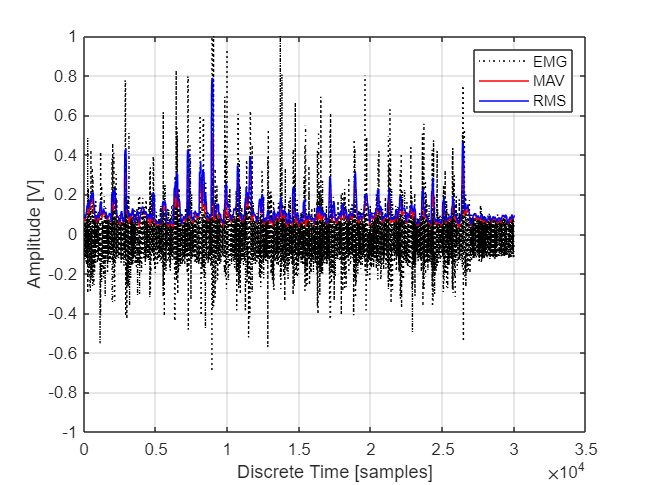

xlabel('Discrete Time [samples]')
ylabel('Amplitude [V]')
ylim([-1 1])
legend()
grid on